## Sergiu Iliev | Bayesian ML Course | Final | Problem 3

## Restricted Boltzmann Machines: Labelling Street View House Numbers (SVHN)

clc, clear

## Data Preparation

### (a) Loading the dataset, converting to grayscale and re-shaping

#### Importing Street Numbers Images Dataset

train_32x32 = load('train_32x32.mat');  % load training dataset
test_32x32 = load('test_32x32.mat');    % load testing dataset

#### Visualize the training dataset

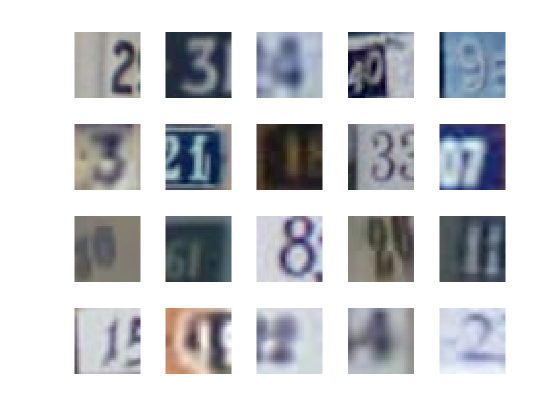

figure;
test_slates_no = size(test_32x32.X, 4);     % find the number of image slates in the test dataset
perm = randperm(test_slates_no,20);         % create an array of 20 random numbers 
for i = 1:20                                % plot 20 random images from the dataset
    subplot(4,5,i);
    imshow(test_32x32.X(:,:,:,perm(i)));
end

#### Convert the images to grayscale

test_img_no = size(test_32x32.X, 4);                 % Find the number of images in the test dataset
for i = 1:test_img_no                                % loop over all test images to convert them to grayscale
    test_32x32_grey.X(:,:,:,i) = rgb2gray(test_32x32.X(:,:,:,i));
end

train_img_no = size(train_32x32.X, 4);                 % Find the number of images in the train dataset
for i = 1:train_img_no                                % loop over all train images to convert them to grayscale
    train_32x32_grey.X(:,:,:,i) = rgb2gray(train_32x32.X(:,:,:,i));
end

#### Visualize the converted images dataset

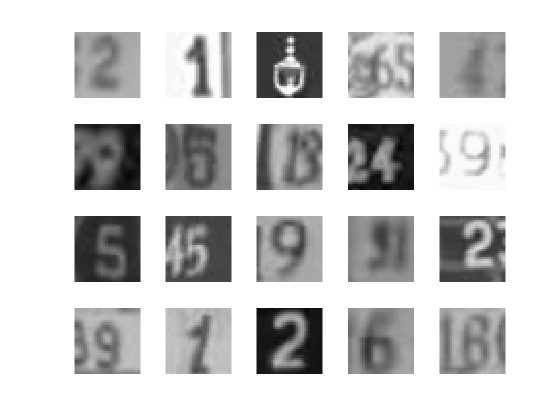

figure;
test_slates_no = size(test_32x32.X, 4);     % find the number of image slates in the test dataset
perm = randperm(test_slates_no,20);         % create an array of 20 random numbers 
for i = 1:20                                % plot 20 random images from the dataset
    subplot(4,5,i);
    imshow(test_32x32_grey.X(:,:,:,perm(i)));
end

#### Reshape and normalize the images into a single vector

% Initialize the Test and Tran Image arrays in which to hold the reshaped normalised immages
images_ts = nan(26032,1024);
images_tr = nan(73257,1024);

% Loop over all test images to convert them to reshape and normalize
for i = 1:test_img_no                               
    test_32x32_grey_reshaped = reshape(test_32x32_grey.X(:,:,:,i),[1024,1]); % reshape into an image vector
    images_ts(i,:) = double(test_32x32_grey_reshaped)/255; % normalize to have the pixel values between 0 and 1 
end

% Loop over all train images to convert them to reshape and normalize
for i = 1:train_img_no                                
    train_32x32_grey_reshaped = reshape(train_32x32_grey.X(:,:,:,i),[1024,1]); % reshape into an image vector
    images_tr(i,:) = double(train_32x32_grey_reshaped)/255; % normalize to have the pixel values between 0 and 1 
end

### b) Preparing the labels for the RBM Model

#### Create arrays with OneHot encoding of the labels ([ref](https://machinelearningmastery.com/why-one-hot-encode-data-in-machine-learning/))

Labels are structured in an one-hot array with 10 columns for each-digit e.g. the third column contains 1s (on) in the rows where the label for the letter 2 and 0s (off otherwise).

labels_ts = transpose(full(ind2vec(test_32x32.y',10)));     % Test labels with one-hot labels for digits 0 to 9
labels_tr = transpose(full(ind2vec(train_32x32.y',10)));    % Train labels with one-hot labels for digits 0 to 9
Nd = size(images_ts,1)                                        % Number of training data points

Nd = 26032

Ni = size(images_ts,2)                                      % Size of the input vector

Ni = 1024

## Training the Restricted Boltzman

### (d) Initialize a Restricted Boltzmann Machine

The following sections build upon Andrea Valent's RBM implementation in MATLAB [ref](https://github.com/Andrea-V/Restricted-Boltzmann-Machine)

% Add path to RBM implementation % forked from https://github.com/Andrea-V/Restricted-Boltzmann-Machine
addpath(genpath([pwd '\RBM'])) ;

% Initlialize the RBM arrays
[M, b, c] = rbm_init(Ni, 100) % Ni = size of the input vector, number of hidden units = 100

M =     0.0004   -0.0098   -0.0090    0.0042   -0.0177   -0.0083    0.0091    0.0015   -0.0105   -0.0306   -0.0171    0.0037   -0.0117   -0.0170   -0.0035    0.0062   -0.0052   -0.0169   -0.0025    0.0063   -0.0020   -0.0209   -0.0119   -0.0012    0.0011   -0.0066    0.0037   -0.0018   -0.0138   -0.0033   -0.0048   -0.0076    0.0042    0.0095    0.0055    0.0008    0.0060   -0.0130   -0.0091   -0.0297   -0.0128   -0.0055    0.0168   -0.0089   -0.0147    0.0065   -0.0210    0.0087   -0.0189    0.0081
    0.0133    0.0034   -0.0059    0.0035   -0.0023    0.0024    0.0009   -0.0084   -0.0270   -0.0020   -0.0088   -0.0036    0.0024   -0.0037   -0.0044    0.0102    0.0019    0.0044   -0.0028    0.0030    0.0147   -0.0111   -0.0070   -0.0274   -0.0050   -0.0250    0.0065   -0.0062   -0.0086    0.0216   -0.0111   -0.0288   -0.0130   -0.0099   -0.0067   -0.0135   -0.0110   -0.0012   -0.0201    0.0051   -0.0095   -0.0232    0.0053   -0.0039   -0.0115    0.0007    0.0071   -0.0082    0.0099    0

b =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


c =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


M, b, c are generated by the RMB initalisation function:

- M (26032 x 100) corresponds to the interaction term between visible units (26032 inputs) and hidden units (100)

- b corresponds to the field term associated with visible units (initialised as zeros - corresponding to no activation)

- c corresponds to the field term associated with hidden units (initialised as zeros - corresponding to no activation)

### (d) Training the Restricted Boltzmann Machine

To begin with we will use the following initial settings (10 minutes training time):

- cd_k = 1; (contrastive-divergence steps)

- eta = 0.01; (learning rate)

- alpha = 0.5; (momentum)

- lambda = 1e-5; (regularization)

- max_epochs = 5 (number of training epochs)

[M , b, c , errors] = rbm_train(images_ts, M, b, c, 1, 0.01, 0.5, 1e-5, 5)

-- shuffling inputs
-- training...
- epoch 0, error: 4.125456
-- shuffling inputs
-- training...
- epoch 1, error: 3.172930
-- shuffling inputs
-- training...
- epoch 2, error: 3.075481
-- shuffling inputs
-- training...
- epoch 3, error: 3.035261
-- shuffling inputs
-- training...
- epoch 4, error: 3.011611
-- shuffling inputs
-- training...
- epoch 5, error: 2.993863
-- shuffling inputs
-- training...
- epoch 6, error: 2.986387


M =     0.0232    0.0815   -0.0902    0.0019   -0.0052    0.1096    0.0537    0.0092    0.0184   -0.0356   -0.1334    0.0289    0.0212   -0.0423   -0.3995    0.0605   -0.0846    0.0312   -0.1081   -0.0785    0.0279    0.0471   -0.0128   -0.0123   -0.2787   -0.4734    0.0060    0.0903    0.0705   -0.0989   -0.0297   -0.0886    0.1436   -0.1637    0.0016    0.0663   -0.0134   -0.1623   -0.0494    0.0024    0.0246   -0.1930    0.0830    0.0047    0.0202    0.0607    0.2936   -0.0878   -0.1248   -0.2937
    0.0142    0.0942   -0.0746   -0.0117   -0.0085    0.1324    0.0446    0.0185    0.0001   -0.0140   -0.1255    0.0259    0.0200   -0.0281   -0.4145    0.0589   -0.0850    0.0195   -0.0642   -0.0941    0.0228    0.0501   -0.0132    0.0157   -0.3048   -0.5077   -0.0192    0.0685    0.0712   -0.0844   -0.0060   -0.0796    0.1428   -0.1785    0.0028    0.0777   -0.0089   -0.1741   -0.0373    0.0005    0.0337   -0.1814    0.0811   -0.0047    0.0287    0.0686    0.2964   -0.0976   -0.1244   -0

b =     0.9648
    0.9528
    0.9350
    0.9241
    0.9152
    0.9125
    0.9012
    0.8981
    0.8957
    0.8922


c =    17.9612
   12.3217
   17.8723
   18.8188
   15.9893
   13.2198
   18.6086
    8.5723
   12.5963
   19.2997


errors =        Inf    4.1255    3.1729    3.0755    3.0353    3.0116    2.9939    2.9864


### (e) Building the encoded representation

Using the trained Boltzmann model we will build an encoded representations of the training and test datasets

img_codes_tr = rbm_encode(images_tr, M, b, c) % encoded representation of the training dataset

img_codes_tr =     0.9999    0.0043    1.0000    1.0000    0.9997    0.9850    1.0000    0.0230    0.9197    1.0000    0.9998    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9124    0.0004    0.9999    1.0000    0.9979    1.0000    0.9476    0.2175    0.5147    1.0000    0.9541    1.0000    1.0000    0.2913    0.0527    0.9603    1.0000    0.8684    1.0000    0.4225    0.1051    1.0000    0.9990    1.0000    0.0000    0.9956    1.0000    1.0000    0.9993    1.0000    0.9999    0.9973    1.0000
    0.9973    0.0028    1.0000    1.0000    0.9982    0.8864    1.0000    0.0000    0.9726    1.0000    0.9997    1.0000    0.9988    0.9997    1.0000    1.0000    1.0000    0.3191    0.0000    0.9998    1.0000    1.0000    0.9993    0.6525    0.0003    0.1150    1.0000    0.5505    0.9999    0.9999    0.0389    0.0002    0.8370    1.0000    0.4120    1.0000    0.9940    0.1106    1.0000    0.9997    1.0000    0.0000    0.9993    0.9999    0.9998    0.9993    1.0000    1.0000    

img_codes_ts = rbm_encode(images_ts, M, b, c) % encoded representation of the test dataset

img_codes_ts =     0.9977    0.1114    1.0000    1.0000    0.9974    0.8827    1.0000    0.0000    0.9961    1.0000    0.9998    1.0000    0.9999    0.9999    0.9999    1.0000    0.9999    0.8801    0.0001    0.9997    1.0000    1.0000    0.9996    0.7820    0.0000    0.0103    1.0000    0.3135    0.9887    0.9999    0.0619    0.0013    0.1714    1.0000    0.7103    1.0000    0.9997    0.0182    1.0000    1.0000    1.0000    0.0000    0.9989    0.9999    0.9998    1.0000    1.0000    1.0000    0.4362    0.9998
    0.0081    0.0000    0.9999    0.3391    0.0001    0.0000    0.0578    0.0000    0.0004    0.9210    0.4544    0.4090    0.9684    0.9812    0.9869    0.9827    0.1036    0.0021    0.0000    0.0396    0.9573    0.7762    0.4430    0.0018    0.0000    0.0000    0.6641    0.0000    0.0000    0.8410    0.0000    0.0000    0.0000    0.8601    0.0000    0.8710    0.0000    0.0000    0.2184    0.9999    0.9980    0.0000    0.0019    0.9780    0.3610    0.9921    1.0000    0.0631    

## Learning the digits

### (f) Initialize a one-layer artificial neural net (ANN)

We will use the encoded representation of the model to train a shallow model using patternnet

*Pattern recognition networks are feedforward networks that can be trained to classify inputs according to target classes. The target data for pattern recognition networks should consist of vectors of all zero values except for a 1 in element *`i`*, where *`i`* is the class they are to represent (*[*ref*](https://www.mathworks.com/help/deeplearning/ref/patternnet.html)*).*

ANN = patternnet(100) % build a neural network with one hidden layer and one output layer.


ANN =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 100
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

### (f) Training the shallow ANN

We can now train the shallow neural net (softmax)

ANN_trained = train(ANN,img_codes_tr',labels_tr')


ANN_trained =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 11110
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

view(ANN_trained);

The trained neural net has the following architecture

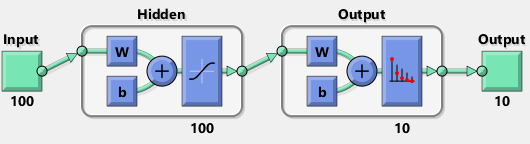

## Testing the performance

### (h) Confusion matrix for trained network on the training data

y_tr = ANN_trained(img_codes_tr') % Feeding the input training data through the trained neural net to obtain the output labels from the RBM

y =     0.5829    0.1185    0.1714    0.0004    0.0042    0.2162    0.3118    0.0168    0.0129    0.0674    0.2491    0.4444    0.3401    0.0016    0.0471    0.0563    0.0012    0.3918    0.1500    0.0322    0.5021    0.0034    0.6563    0.5733    0.0372    0.2120    0.0060    0.0131    0.0238    0.0370    0.7965    0.0053    0.0956    0.1641    0.0001    0.0072    0.4998    0.0743    0.2258    0.0016    0.0002    0.0970    0.1261    0.0011    0.1063    0.5646    0.0215    0.1057    0.0422    0.1348
    0.0621    0.0571    0.0229    0.1560    0.8422    0.0041    0.2236    0.0377    0.0690    0.0329    0.1937    0.0018    0.3852    0.0024    0.0646    0.0029    0.0038    0.0266    0.4945    0.0126    0.0433    0.0024    0.0442    0.0119    0.0035    0.1344    0.0022    0.6981    0.0426    0.0140    0.0914    0.0016    0.1227    0.0616    0.0053    0.0249    0.0928    0.0935    0.1090    0.9331    0.9135    0.1006    0.1378    0.8651    0.0384    0.0098    0.0125    0.0637    0.0476    0

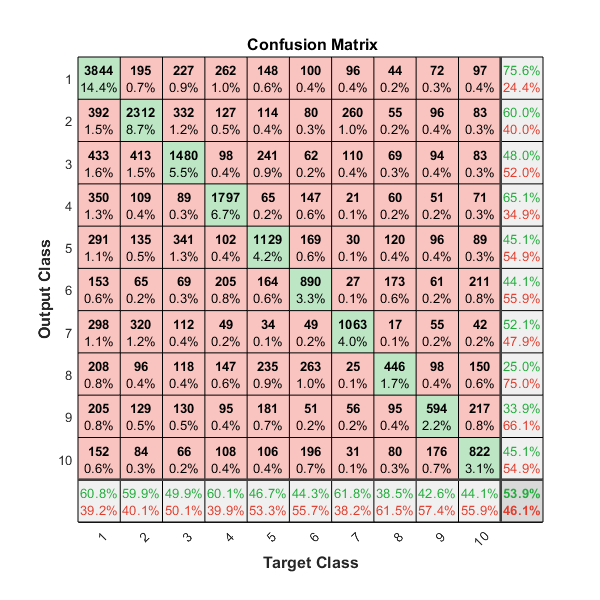

plotconfusion(y_tr, labels_tr')  % Confusion matrix for trained network on the training data

### (i) Predicting the labels for the training dataset

Unlike in the case for y_training, we are now evaluating the RBM ML model using previously unseen test data

y_ts =  ANN_trained(img_codes_ts') % feeding the encoded test images data to the RBM ANN model to predict the labels for this new, previously unseen, data

y_ts =     0.0775    0.0255    0.3020    0.1094    0.0158    0.8621    0.4538    0.9588    0.8009    0.0000    0.3860    0.0240    0.0751    0.5307    0.0000    0.0096    0.2248    0.0434    0.1358    0.0056    0.0006    0.0020    0.7753    0.1557    0.0002    0.0009    0.0066    0.3820    0.0050    0.2703    0.0011    0.0047    0.0046    0.2021    0.7052    0.9549    0.0002    0.8769    0.5300    0.0181    0.0583    0.3222    0.0016    0.9742    0.1599    0.0144    0.7815    0.1415    0.0437    0.2351
    0.1847    0.5773    0.1721    0.0891    0.0496    0.0155    0.0400    0.0005    0.0544    0.0027    0.0039    0.0505    0.1176    0.0200    0.0001    0.0013    0.0727    0.0095    0.0203    0.0001    0.6974    0.0000    0.0279    0.0268    0.9810    0.0002    0.0020    0.0137    0.0076    0.3359    0.0013    0.4168    0.0311    0.0167    0.0324    0.0071    0.0001    0.0164    0.0092    0.6895    0.0346    0.0522    0.0028    0.0003    0.0465    0.0145    0.0366    0.3974    0.0868  

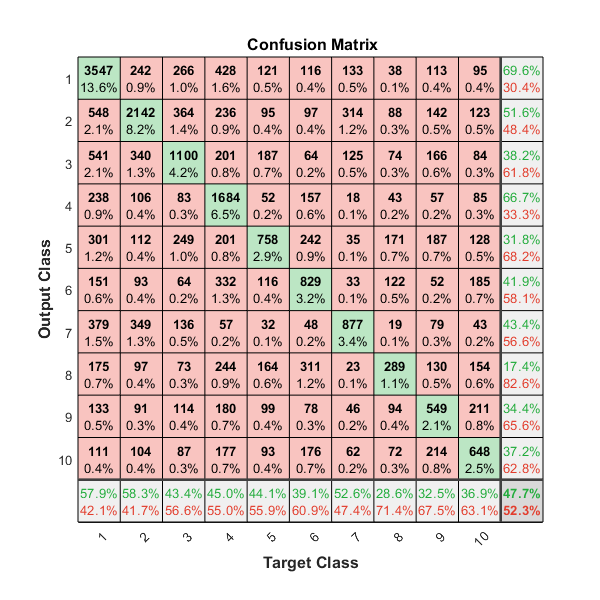

plotconfusion(y_ts, labels_ts')  % Confusion matrix for trained network on the training data

Looking at the two confusion matrices above we can observe that:

- the erros are overall higher for the test dataset, which is to be expected as the model was bilnd to this set during testing

- errors do not increase significantly between the two matrices, suggesting that the model is generalizable and not overfitted to the test data

- the number that were confused the most was 0, especially with lower value digits like 0,1,2,3,4 -- this might also be due to the fact that the dataset is bias to the digit 0 (more of these examples than for other digits)

## Visualizing the filters

### **(j) Converting from M vector space back to the image space**

To visualise the filters we will convert back from encoded space `M` to the original image space of 32 x 32 pixels `M_images`

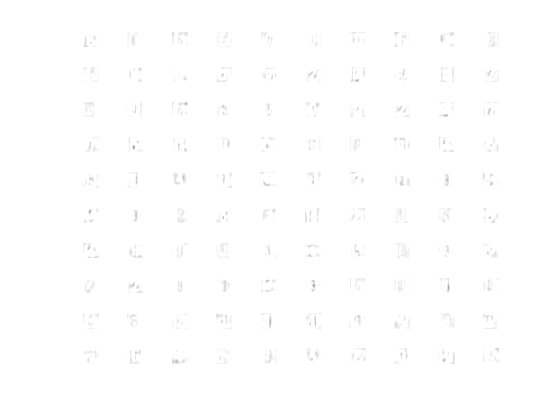

figure
hold on
for i=1:size(M,2)                       % Loop over all of the columns of the M matrix (all 100 layers)
   subplot(10, 10, i);                  % Create a subplot of the 100 filters into a 10×10 grid
   M_images = reshape(M(:,i), 32, 32);  % Reshape the filters in M by converting each of the filter vector into
   imshow(1-M_images)                   % Swap the black and white colors to make the filters easily visible and display the image
%    title(sprintf('unit %d', i));      % Used to generate the larger image included below
end

### **(k) Larger view of the 100 filters visualisation showing the pixel activation of each filter (black pixels)**

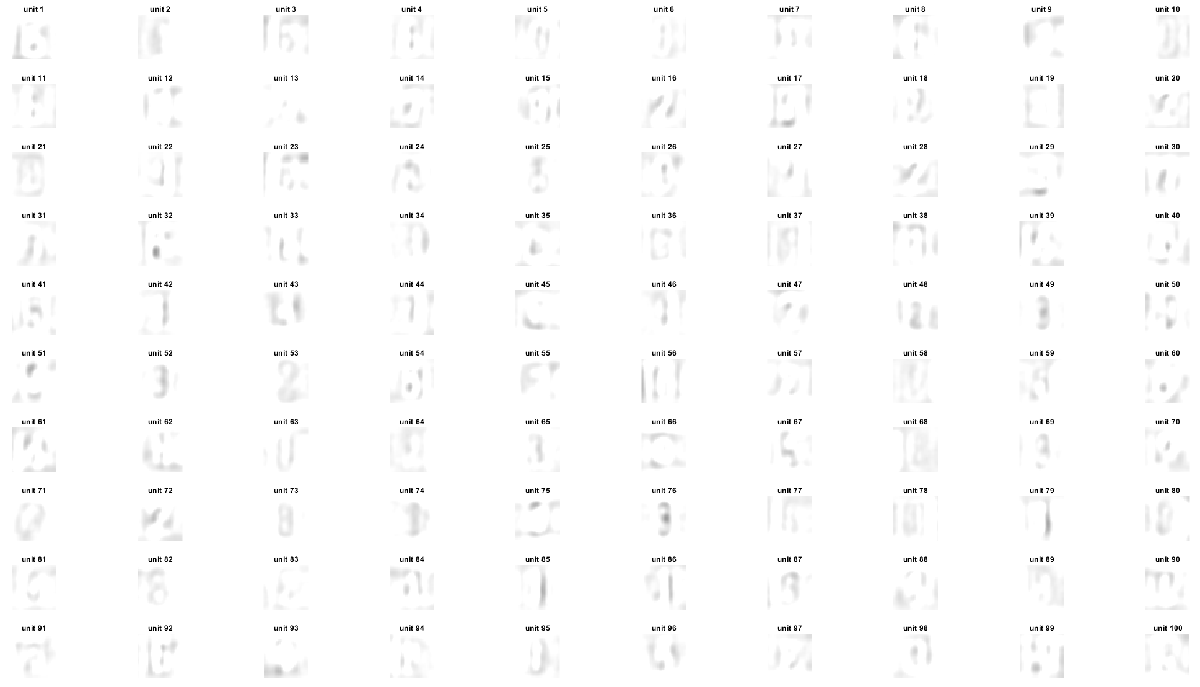

### **(l) Identifying the most important filters**

We can find the most important filters by looking at the coefficient vector, `c` which corresponds to the field term associated with hidden units.

ntop = 5;                       % number of top filters to extract
[val, ind] = sort(c,'ascend');  % sort the filters

figure
hold on
for i=1:ntop                                     % Loop over all max activation ntop filters
   subplot(1, 5, i);                             % Create a subplot of the max ntop filters into a 1×5 grid
   % Reshape the filters in M by converting each of the filter vector into an image and select just the columns (hidden nodes) with the indices found previously
   M_image = reshape(M(:,ind(i)), 32, 32); 
   imshow(1-M_image)                             % Swap the black and white colors to make the filters easily visible and display the image
   title(sprintf('unit %d', ind(i)));            % Include the index name
end  

I think these are emerging as the top 5 most important filters because they are the most general, unlike other more specialised hidden layers, these activate for most digits in the dataset ([ref](https://www.cs.toronto.edu/~hinton/absps/guideTR.pdf)). It is particularly interesting to observe `unit 57`, which has the shape used by many digital clocks displays (the 7-Segment) as it best encodes all digits using the minium number of lines.

**The 7-Segment, similar to unit 57 in the Restricted Boltzmann Machine trained on the Street View House Numbers (SVHN) Dataset**

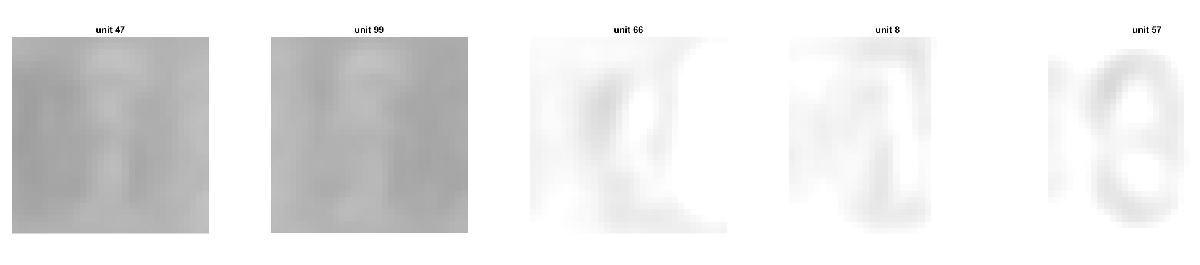top 5 RBM filters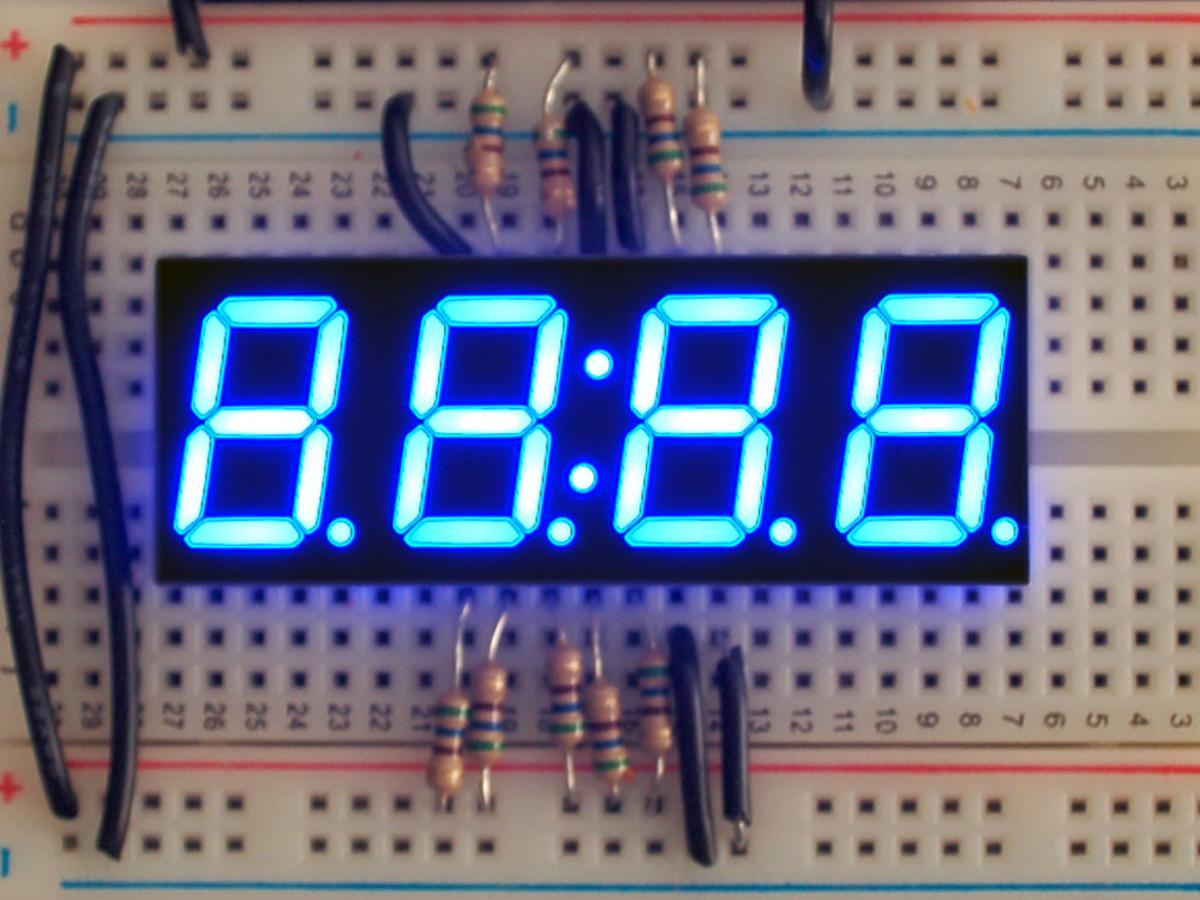 7 segment clock display fully activated ([ref](https://www.adafruit.com/product/812))